# 1. Transfer Learning 

## Overview of Pretrained Convolutional Neural Networks

Load AlexNet into a network variable in MATLAB

 net = alexnet   % Error? Then, install 'Deep Learning Toolbox Model for AlexNet Network' in Add-Ons Explorer

Peek into AlexNet

% View the layers of AlexNet and save the layers to a variable
layers = net.Layers

% Save the first and last layers of AlexNet
layers_input = layers(1)
layers_output = layers(end)

% View the output classes of AlexNet
classed = layers_output.Classes

## Preprocessing an Image

Import an image and resize it to be compatible with AlexNet

% Display an image
image1 = imread("harper.jpg")
imshow(image1)

% View the input size of AlexNet
layers_input.InputSize

% Resize the image so that it can be applied to AlexNet
image1_resized = imresize(image1,[227,227])
imshow(image1_resized)

% Classify the image
%prediction = classify(net, image1_resized)

% Classify the image and see the score
%[prediction, score] = classify(net,image1_resized)
%max(score)

im = single(image1_resized)
scores = predict(net, im)
[testPredm, score] = scores2label(scores, classed)



## Image Datastore

When you import large data, you don't have to save them as variables because it costs too much time and memory. 

Instead, you can read image files by creating a datastore, which references a data source such as a folder of image files. When you create a datastore, basic information such as the file name and formats is stored.

% Create an image datastore referring to 'Lucy'
%imageDS = imageDatastore("C:\Users\medan\Desktop\24-2 과제\인공지능\petImages\petImages\Lucy",...
%    "includeSubfolders",true, "LabelSource", "foldernames")

imageDS = imageDatastore("/Users/idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy",...
    "includeSubfolders",true, "LabelSource", "foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy103.jpg';
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy104.jpg';
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy105.jpg'
                               ... and 29 more
                              }
                     Folders: {
                              '/Users/idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy'
                              }
                      Labels: [Lucy; Lucy; Lucy ... and 29 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatas

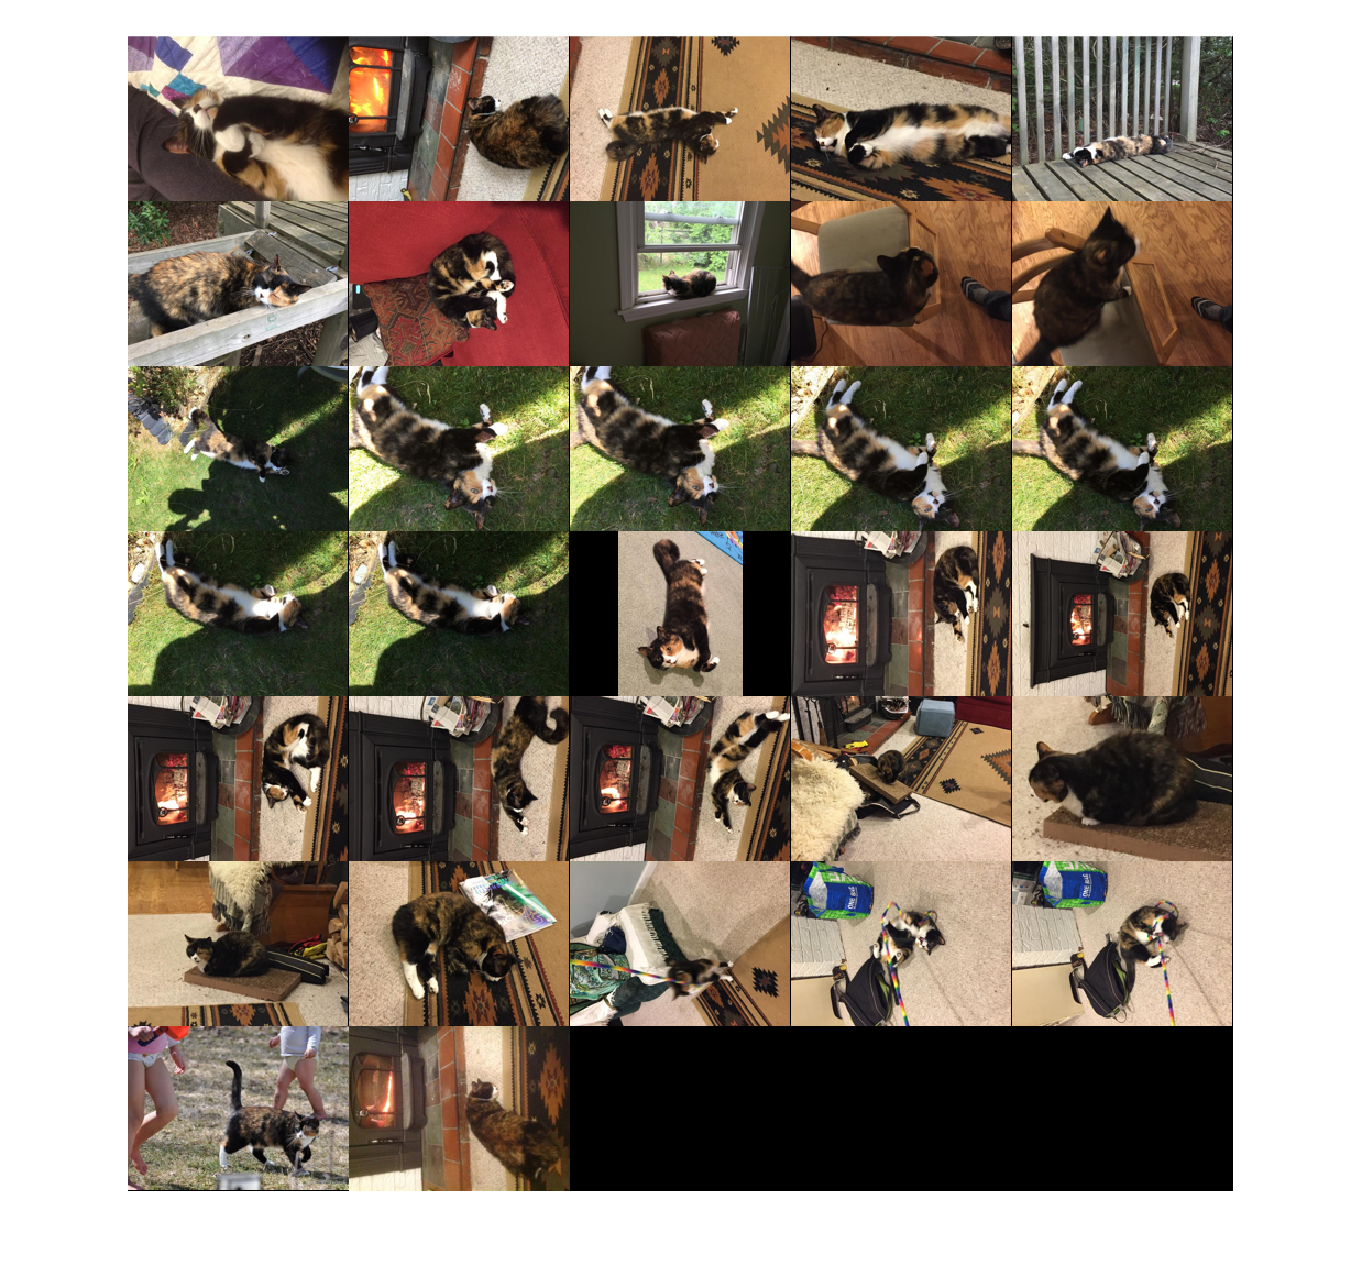


% Read and display 'Lucy' images
    % imageAll = imtile(imageDS)
    % imshow(imageAll) 
montage(imageDS)


augImageDS = augmentedImageDatastore([227,227], imageDS)

augImageDS =   augmentedImageDatastore - 속성 있음:

             NumObservations: 32
                       Files: {32×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


For the images in an image datastore, basic preprocessing can be done by `augmentedImageDatastore` function

## Modifying a Pretrained Network

An existing pretrained network does not ouput the classes you want. When performing transfer learning, you will typically change the fully connected layer and the classification layer to suit your specific application. 

clear    % clear
% Load AlexNet and view the layers and the output classes
net = imagePretrainedNetwork("alexnet")

net =   dlnetwork - 속성 있음:

         Layers: [24×1 nnet.cnn.layer.Layer]
    Connections: [23×2 table]
     Learnables: [16×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  요약 보기(summary 참조).


layers = net.Layers

layers =   다음 계층을 포함한 24×1 Layer 배열:

     1   'data'    영상 입력               227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'   2차원 컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'   ReLU                  ReLU
     4   'norm1'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'   2차원 그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'   ReLU                  ReLU
     8   'norm2'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'   2차원 컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'   ReLU                  ReLU
    12   'conv4'   2차원 그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'

Change the number of output classes by modifying the fully conneceted layer(23) and the classification layer(25).


layers(23) = fullyConnectedLayer(14);

## Preparing Training Data

% Create an image datastore with the images labeled by their folder name
%imageDS = imageDatastore("C:\Users\medan\Desktop\24-2 과제\인공지능\petImages",...
%    "IncludeSubfolders",true,"LabelSource","foldernames")

imageDS = imageDatastore("/Users/idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy",...
    "includeSubfolders",true, "LabelSource", "foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy103.jpg';
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy104.jpg';
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy105.jpg'
                               ... and 29 more
                              }
                     Folders: {
                              '/Users/idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy'
                              }
                      Labels: [Lucy; Lucy; Lucy ... and 29 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatas



% Split the data into training and test data sets
[trainImages, testImages] = splitEachLabel(imageDS, 0.8)

trainImages =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy103.jpg';
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy104.jpg';
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy105.jpg'
                               ... and 23 more
                              }
                     Folders: {
                              '/Users/idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy'
                              }
                      Labels: [Lucy; Lucy; Lucy ... and 23 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readD

testImages =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy129.jpg';
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy130.jpg';
                              ' .../idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy/Lucy131.jpg'
                               ... and 3 more
                              }
                     Folders: {
                              '/Users/idanbi/Desktop/24ai/24-2-AI/petImages/petImages/Lucy'
                              }
                      Labels: [Lucy; Lucy; Lucy ... and 3 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readData


% Create augmented datastores to resize the images so that they can be applied to AlexNet
trainData = augmentedImageDatastore([227,227], trainImages)

trainData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 26
                       Files: {26×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testData = augmentedImageDatastore([227,227],testImages)

testData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 6
                       Files: {6×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## Training Options

Use Stochastic Gradient Descent with Momentum (SGDM) and decrease the initial learning rate to 0.0001.

The default initial learning rate is 0.01 but generally it should be decreased for better performances in a transfer learning.

## Training and Evaluating the Network

Train a new network. In order to use a GPU instead of a CPU, install 'Parallel Computing Toolbox' in Add-Ons explorer. A GPU is much faster than a CPU in training a neural network.

Evaluate the network by classifying the test data

    % Prediction by the new network
    % Ground truth of the test data
    % Prediction Accuracy
    % Visualization in a confusion matrix
